# 绘制旋转多边形

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

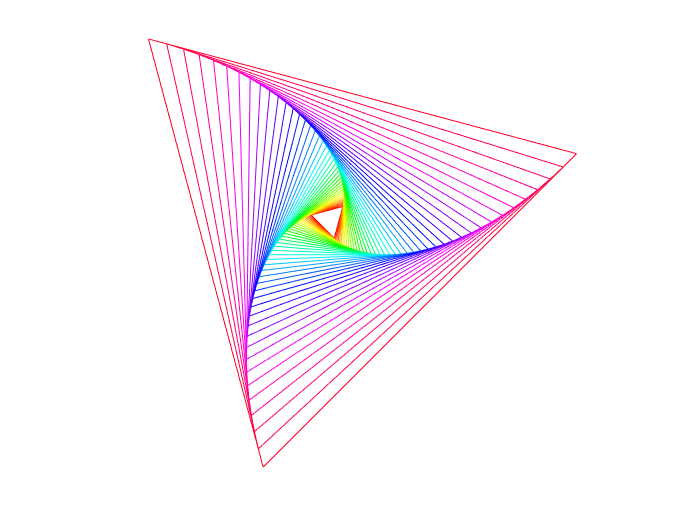

clear;clc;close all;
m = 3;
n = 41;
d_angle = 2.25;
rotate = 45;
shift = [0, 0];
figure
SpiralPolygon(m, n, d_angle, rotate, shift);

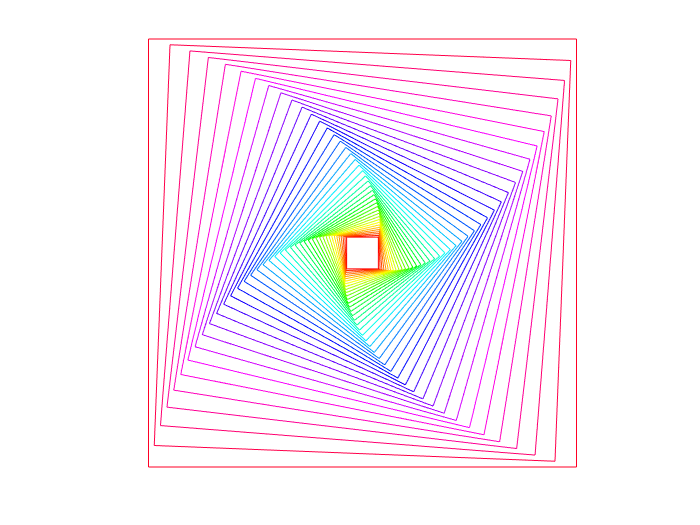

m = 4;
figure
SpiralPolygon(m, n, d_angle, rotate, shift);

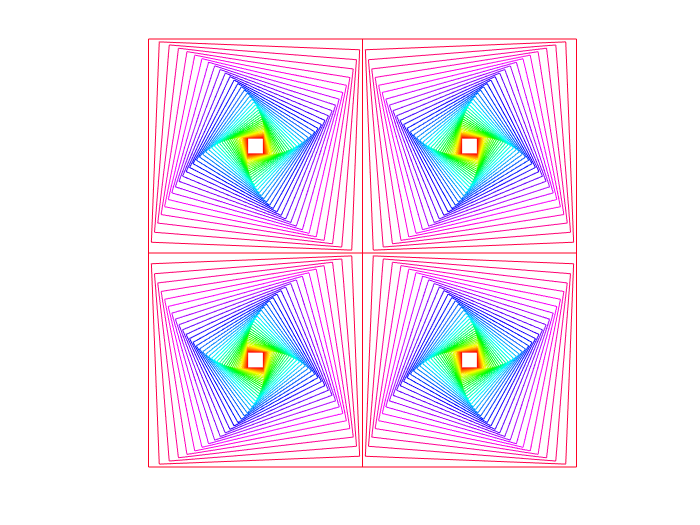

figure;
V = SpiralPolygon(m, n, -d_angle, rotate, shift);
hold on
dx = max(V(1, :)) - min(V(1, :));
dy = max(V(2, :)) - min(V(2, :));
shift = [dx, 0];
SpiralPolygon(m, n, d_angle, rotate, shift);
shift = [dx, dy];
SpiralPolygon(m, n, -d_angle, rotate, shift);
shift = [0, dy];
SpiralPolygon(m, n, d_angle, rotate, shift);
hold off

function V = SpiralPolygon(m, n, d_angle, rotate, shift)
th = linspace(0, 360, m + 1) + rotate;
V = [cosd(th); sind(th)];
C = colormap(hsv(n));
scale = sind(150 - abs(d_angle))/sind(30);
R = Rot2(d_angle);
% hold off
for i = 1:n
    if i > 1
        V = scale * R * V;
    end
    plot(V(1,:) + shift(1), V(2,:) + shift(2), 'Color', C(i,:));
    hold on
end
set(gcf, 'Color', 'w');
axis equal
axis off
end

function R = Rot2(theta)
theta = theta*pi/180;
R = [cos(theta), -sin(theta); sin(theta), cos(theta)];
end